% stackedBarhBarDumbbellBemo
% @author : slandarer
% 公众号  : slandarer随笔
% 知乎    : slandarer

% 数据导入
Data=readtable('ta_results_revisions_data.csv');
[N,~]=size(Data);

## ========================================================================

figure窗口及axes坐标区域创建

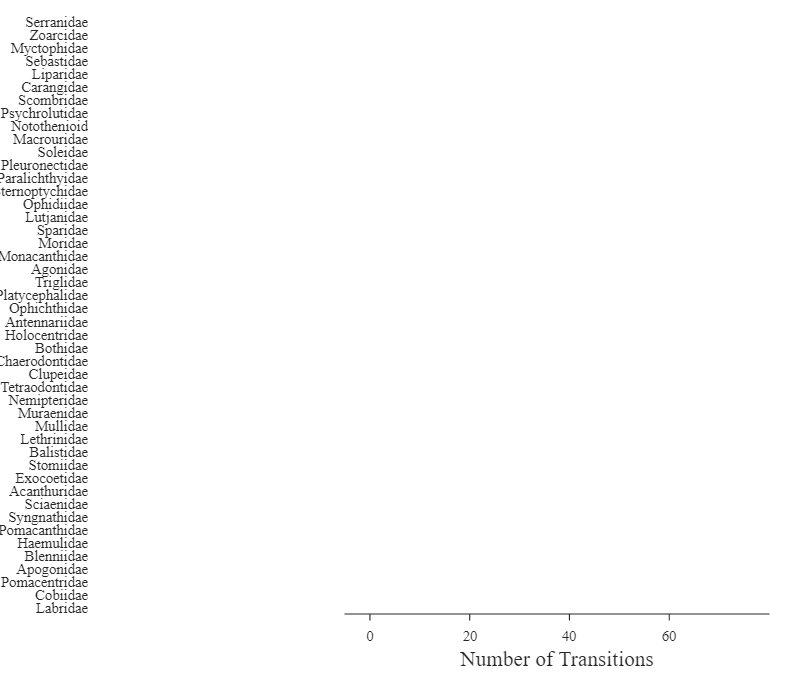

fig=figure('Units','normalized','Position',[.1,.05,.55,.85],'Color',[1,1,1]);
% -------------------------------------------------------------------------
% 左侧柱状图axes
ax1=axes(fig);
ax1.NextPlot='add';
ax1.Position=[.12,.1,.3,.88];
ax1.XLim=[-.01,1];
ax1.YLim=[.5,N+.5];
plot(ax1,[-.01,-.01],[.5,N+.5],'Color',[1,1,1],'LineWidth',2)
ax1.YTick=1:N;
ax1.TickLength=[1e-5,14-5];
ax1.YTickLabel=Data.Name;
ax1.YDir='reverse';
ax1.XColor='none';
ax1.FontName='Times New Roman';
ax1.FontSize=11;
% -------------------------------------------------------------------------
ax2=axes(fig);
ax2.NextPlot='add';
ax2.Position=[.44,.1,.54,.88];
ax2.FontName='Times New Roman';
ax2.YColor='none';
ax2.XLim=[-5,80];
ax2.YLim=[.5,N+.5];
ax2.XTick=[0,20,40,60];
ax2.LineWidth=.8;
ax2.TickDir='out';
ax2.FontSize=11;
ax2.XLabel.String='Number of Transitions';
ax2.XLabel.FontSize=16;

## ========================================================================

左侧堆叠柱状图绘制

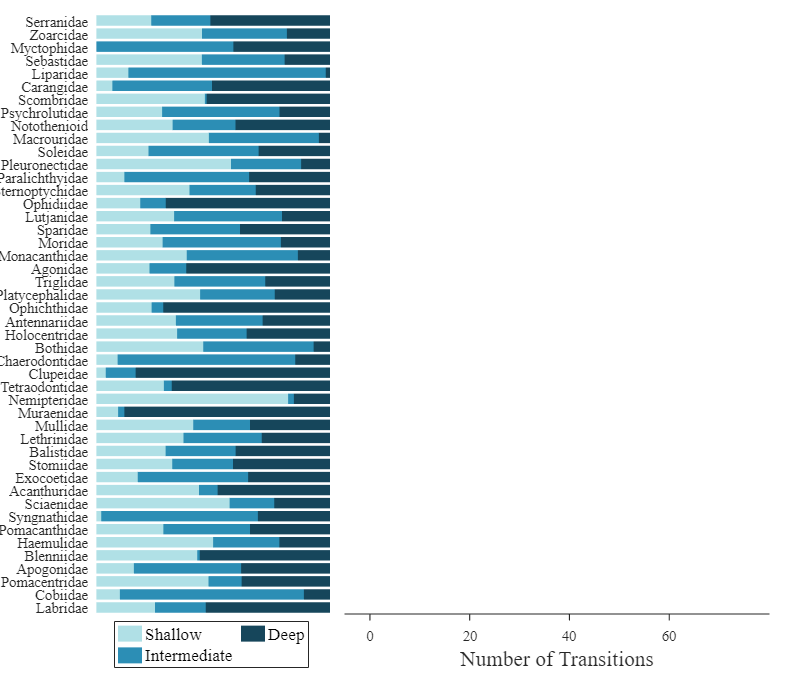

barhHdl=barh(ax1,[Data.Shallow,Data.Intermediate,Data.Deep],'stacked');
% 修改配色
barhHdl(1).EdgeColor='none';
barhHdl(2).EdgeColor='none';
barhHdl(3).EdgeColor='none';
barhHdl(1).FaceColor=[176,224,230]./255;
barhHdl(2).FaceColor=[44,142,181]./255;
barhHdl(3).FaceColor=[22,70,91]./255;
% 绘制图例
lgd1Hdl=legend(ax1,barhHdl,{'Shallow','Intermediate','Deep'});
lgd1Hdl.NumColumns=2;
lgd1Hdl.ItemTokenSize=[18,18];
lgd1Hdl.Position=[.17,.02,.2,.07];
lgd1Hdl.FontSize=13;

## ========================================================================

右侧哑铃图绘制 绘制灰色线条

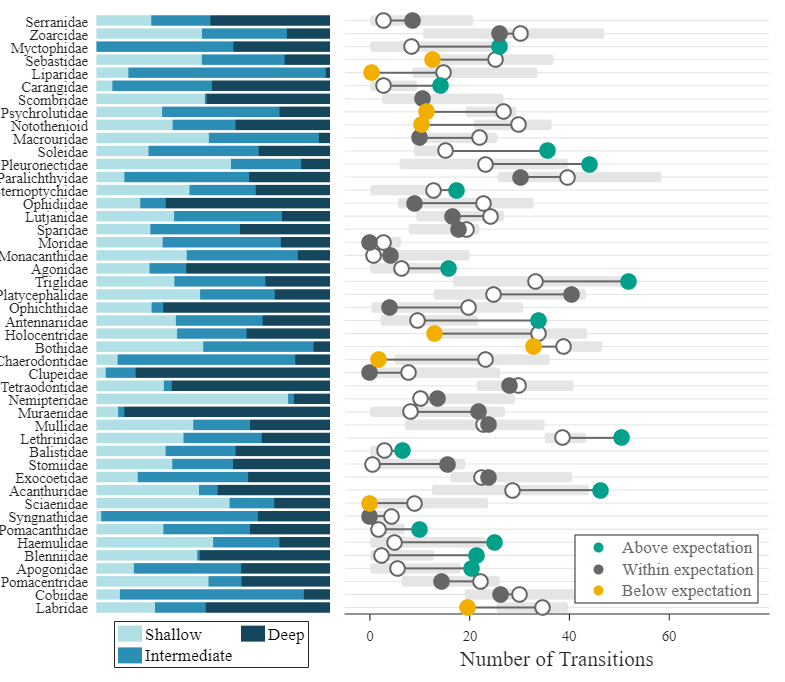

XX=repmat(ax2.XLim,[N,1])*[1,0,nan;0,1,nan];
YY=repmat((1:N)',[1,3]);XX=XX';YY=YY';
plot(ax2,XX(:),YY(:),'LineWidth',.8,'Color',[229,229,229]./255)
% 绘制圆角矩形
for i=1:N
rectangle(ax2,'Position',[Data.Low(i),i-.4,Data.High(i)-Data.Low(i),.8],...
    'EdgeColor','none','FaceColor',[229,229,229]./255,'Curvature',1)
end
% 绘制中值点与实际值连线
NXX=[Data.Median,Data.Exact]*[1,0,nan;0,1,nan];NXX=NXX';
plot(ax2,NXX(:),YY(:),'LineWidth',.8,'Color',[102,102,102]./255,'LineWidth',1.5)
% 绘制中值处圆点
scatter(ax2,Data.Median,1:N,120,'filled','o','MarkerFaceColor',[1,1,1],...
    'MarkerEdgeColor',[102,102,102]./255,'LineWidth',1.5)
% 绘制实际值圆点
scAHdl=scatter(ax2,Data.Exact(Data.Exact>Data.High),find(Data.Exact>Data.High),...
    120,'filled','o','MarkerFaceColor',[0,160,138]./255,'MarkerEdgeColor',[0,160,138]./255,'LineWidth',1.5);
scWHdl=scatter(ax2,Data.Exact(Data.Exact<=Data.High&Data.Exact>=Data.Low),find(Data.Exact<=Data.High&Data.Exact>=Data.Low),...
    120,'filled','o','MarkerFaceColor',[102,102,102]./255,'MarkerEdgeColor',[102,102,102]./255,'LineWidth',1.5);
scBHdl=scatter(ax2,Data.Exact(Data.Exact<Data.Low),find(Data.Exact<Data.Low),...
    120,'filled','o','MarkerFaceColor',[241,175,1]./255,'MarkerEdgeColor',[241,175,1]./255,'LineWidth',1.5);
% 绘制图例
lgd2Hdl=legend(ax2,[scAHdl,scWHdl,scBHdl],{'Above expectation','Within expectation','Below expectation'});
lgd2Hdl.Location='southeast';
lgd2Hdl.FontSize=13;
lgd2Hdl.TextColor=[.4,.4,.4];